# Homework 1.2

Simulation for the RLC circuit.

## Set parameters for the circuit

clearvars;
R = 100;
C = 100e-6;
L = 0.1;
A = [0, -1/L; 1/C, -1/(R*C)];
B = [1/L, -1/L; 0, -1/(R*C)];
C = [1, 0; 1, -1/R];
D = [0, 0; 0, -1/R];

## Discretization

dt = 0.0001;
syms ss;
A_d = double(ilaplace(inv(ss*eye(size(A,1)) - A), 0.001));
B_d = A\(A_d - eye(size(A,1)));
B_d = B_d * B;
C_d = C;
D_d = D;

## Simulation

Simulation for 10s;

T = 1;
TT = T/dt;
e_1 = 60.0 * cos(dt*(50*(0:TT)));
e_2 = 30.0 * sin(dt*(50*(0:TT)));
x = zeros(2, TT+1);
y = zeros(2, TT+1);
for t = 1:TT
    [x(:, t+1), y(:, t)] = ssforward(x(:, t), [e_1(t); e_2(t)], A_d, B_d, C_d, D_d);
end
y(:, TT+1) = C_d * x(:, TT+1) + D_d * [e_1(TT+1); e_2(TT+1)];

## Plot

Show results

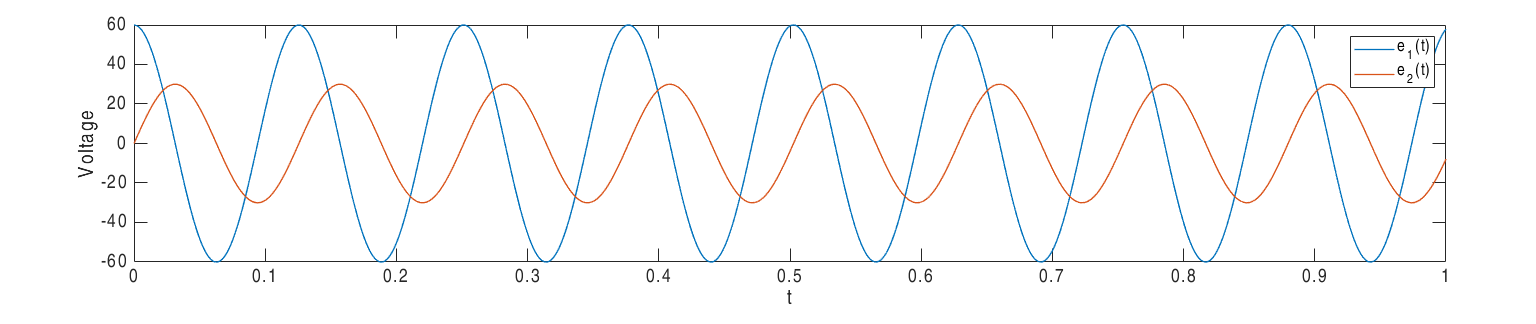

configs.LineWidth=1.0;
figure, plot(dt*(0:TT), [e_1', e_2'], configs), ylabel('Voltage'), xlabel('t');
legend({'e_1(t)', 'e_2(t)'});
tight_layout([0.8, 0.3], 14);

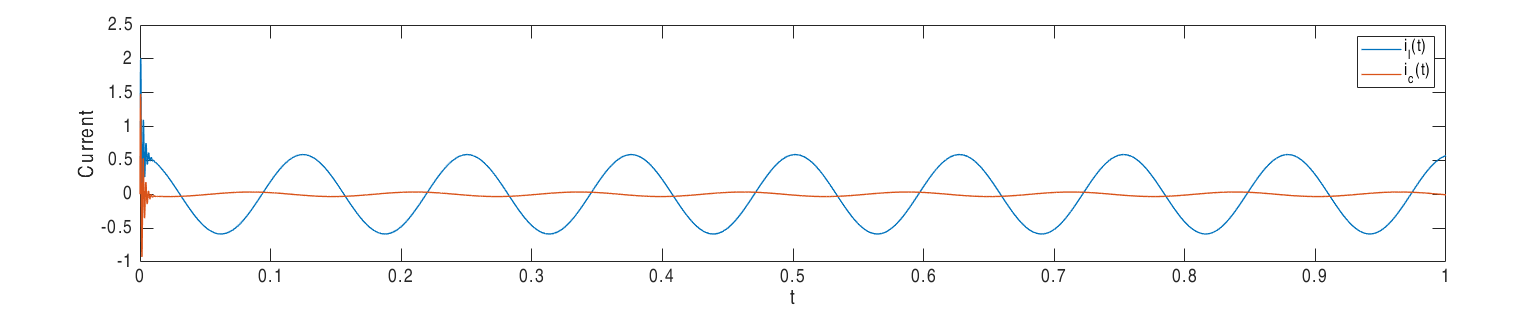

figure, plot(dt*(0:TT), [x(1,:)', y(2,:)'], configs), ylabel('Current'), xlabel('t');
legend({'i_l(t)', 'i_c(t)'});
tight_layout([0.8, 0.3], 14);

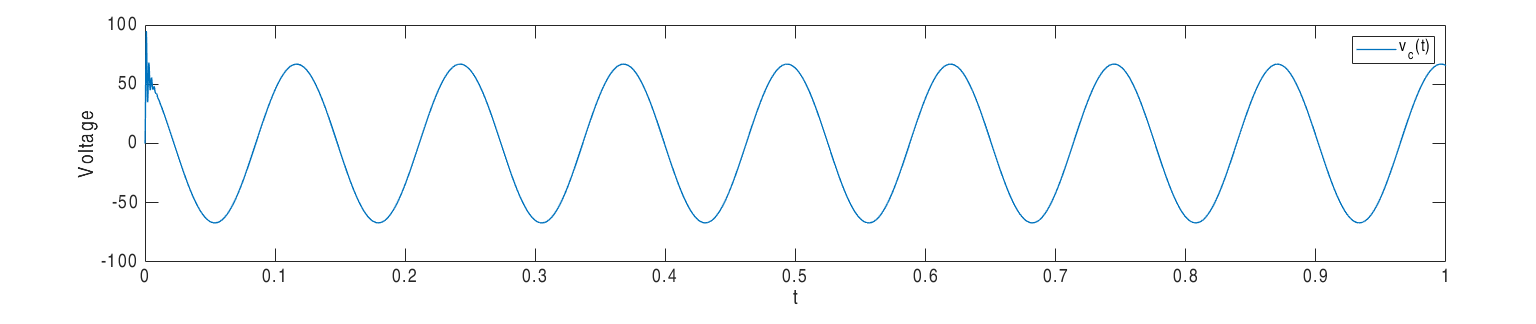

figure, plot(dt*(0:TT), x(2,:)', configs), ylabel('Voltage'), xlabel('t');
legend({'v_c(t)'});
tight_layout([0.8, 0.3], 14);

# Functions

## Forward propagation of SS model

- xk: current states.

- uk: current inputs;

- A, B, C, D: discretized transmission matrix.

function [xkp, yk] = ssforward(xk, uk, A, B, C, D)
    xkp = A * xk + B * uk;
    yk = C * xk + D * uk;
end